Colin Keenan

ECE 5470

4-27-2020

# Homework 11

1.  Erosion and Dilation

clear

fprintf("Question 1:")

Question 1:

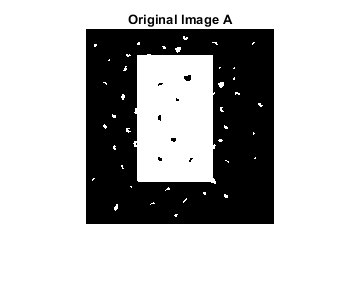


scale = 0.15;

A = im2double(imresize(imread('Fig7-1.tif'),scale));
B = im2double(imresize(imread('B.tif'),scale));

C = erode(A,B);
D = dilate(C,B);
E = dilate(D,B);
F = erode(E,B);

figure();
imshow(A);
title('Original Image A');

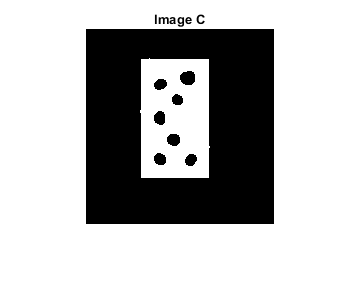

figure();
imshow(C);
title('Image C');

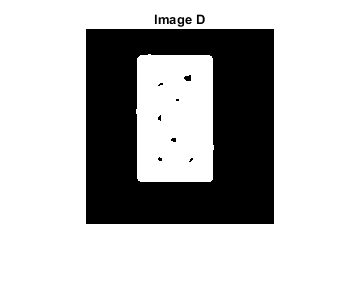

figure();
imshow(D);
title('Image D');

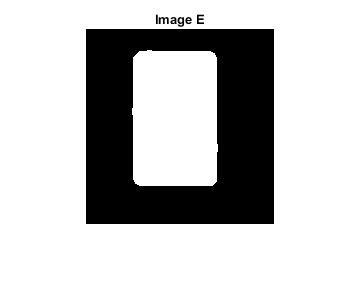

figure();
imshow(E);
title('Image E');

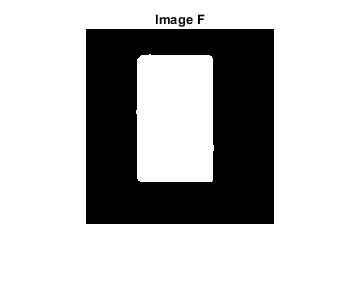

figure();
imshow(F);
title('Image F');

2. Hole Filling

clear

fprintf("Question 2:")

Question 2:

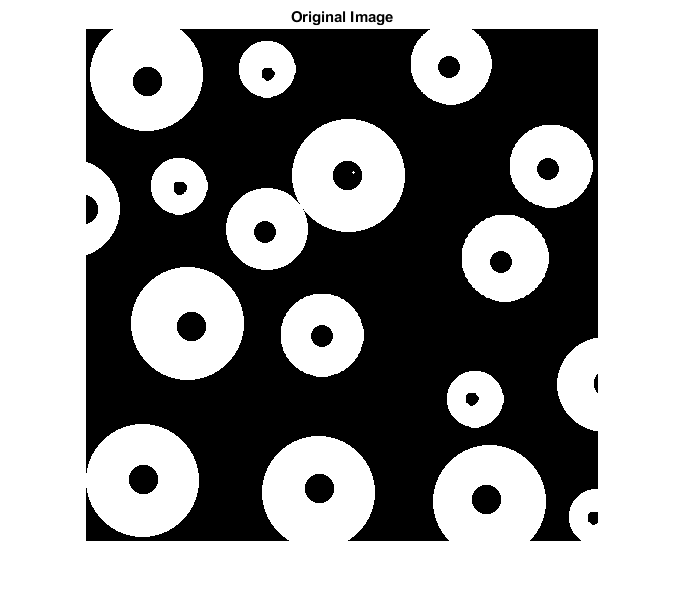


image = im2double(imread('Fig7-2(2).tif'));
imageComp = 1-image;

start = [95,239];
struct = [[0 1 0]
          [1 1 1]
          [0 1 0]];
      
filled = close(image,struct);

figure, imshow(image);
title('Original Image');

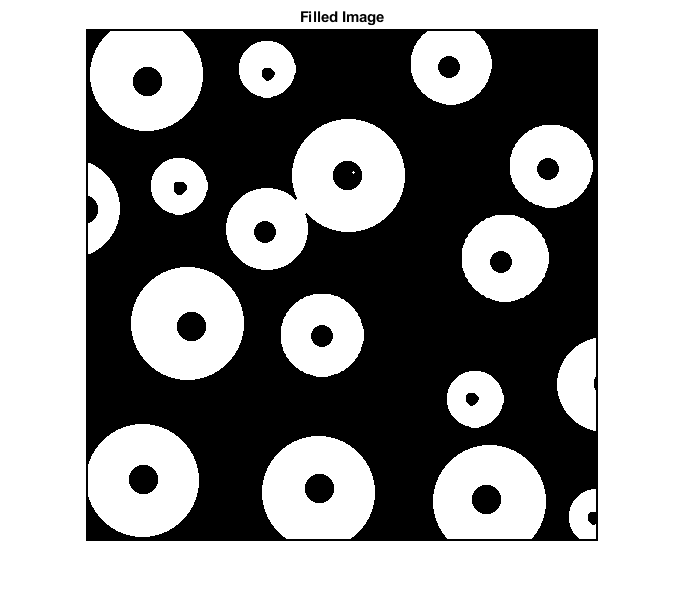

figure, imshow(filled);
title('Filled Image');

3. Image Fix

clear

fprintf("Question 3:")

Question 3:

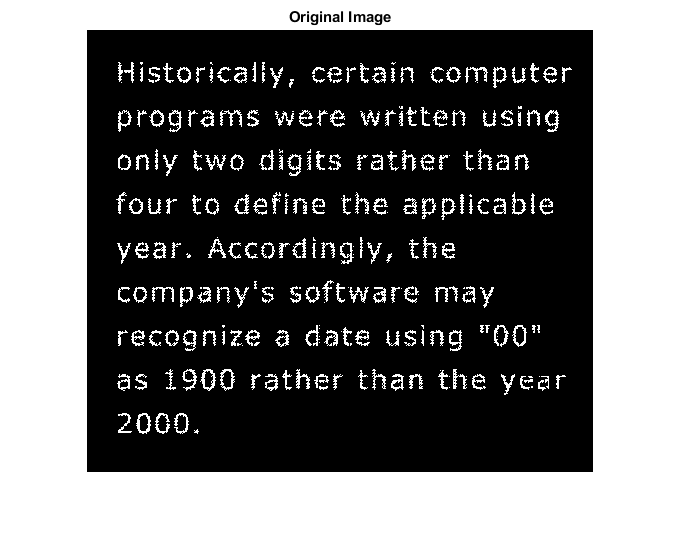


image = im2double(imread('Fig7-3.tif'));

struct1 = [[1 1 1]
           [1 1 1]
           [1 1 1]];
       
struct2 = [[0 1 0]
           [1 1 1]
           [0 1 0]];

imageMod = close(image,struct2);
imageMod = close(imageMod,struct2);
imageMod = bwperim(imageMod);
imageMod = close(imageMod,struct1);
imageMod = close(imageMod,struct2);

figure, imshow(image);
title('Original Image');

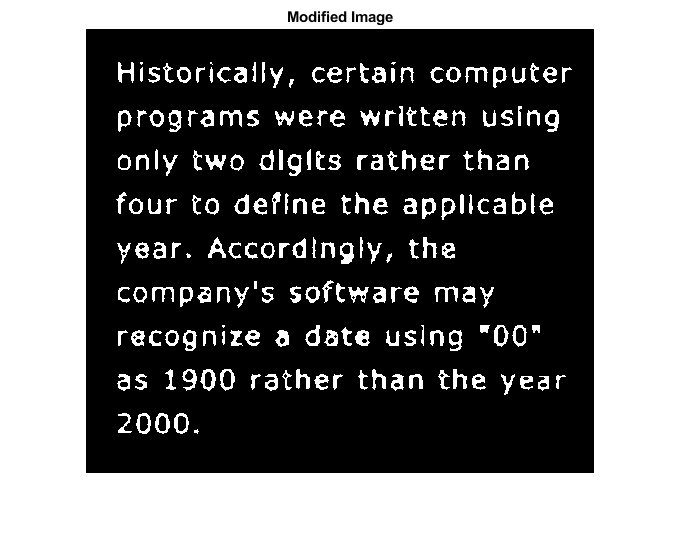

figure, imshow(imageMod);
title('Modified Image');

## Appendix (Functions Used)

function eroded = erode(image, struct)
    eroded = zeros(size(image));
    frame = zeros(size(struct));
    pad = floor(size(struct,1)/2);

    for i = 1+pad : size(image,1)-pad
        for j = 1+pad : size(image,2)-pad
            
            % Get Current Frame
            xOffset = -1*pad-1;   
            for x = 1:size(frame,1)
                yOffset = -1*pad;
                xOffset = xOffset + 1;
                for y = 1:size(frame,2)
                    frame(x,y) = image(i+xOffset,j+yOffset);
                    yOffset = yOffset + 1;
                end
            end
           
            if((frame & struct) == struct)
                eroded(i,j) = 1;
            else
                eroded(i,j) = 0;
            end
        end
    end
end

function dilated = dilate(image, struct)
    dilated = zeros(size(image));
    frame = zeros(size(struct));
    pad = floor(size(struct,1)/2);
    
    for i = 1+pad : size(image,1)-pad
        for j = 1+pad : size(image,2)-pad
            
            % Get Current Frame
            xOffset = -1*pad-1;   
            for x = 1:size(frame,1)
                yOffset = -1*pad;
                xOffset = xOffset + 1;
                for y = 1:size(frame,2)
                    frame(x,y) = image(i+xOffset,j+yOffset);
                    yOffset = yOffset + 1;
                end
            end
                       
            if((frame & struct) == 0)
                dilated(i,j) = 0;
            else
                dilated(i,j) = 1;
            end
       
        end
    end
end

function filled = fill(image, struct, start)
% Not working
    filled = image;
    imageC = 1-image;
    frame = zeros(size(struct));
    frameC = zeros(size(struct));
    pad = floor(size(struct,1)/2);

    for i = start(2) : size(image,1)-pad
        for j = 1+pad : size(image,2)-pad
            % Get Current Frame
            xOffset = -1*pad-1;   
            for x = 1:size(frame,1)
                yOffset = -1*pad;
                xOffset = xOffset + 1;
                for y = 1:size(frame,2)
                    frame(x,y) = image(i+xOffset,j+yOffset);
                    frameC(x,y) = imageC(i+xOffset,j+yOffset);
                    yOffset = yOffset + 1;
                end
            end
            
            dilated = dilate(frame,struct);
            restrict = dilated&frameC;
            
            xOffset = -1*pad-1;   
            for x = 1:size(frame,1)
                yOffset = -1*pad;
                xOffset = xOffset + 1;
                for y = 1:size(frame,2)
                    filled(i+xOffset,j+yOffset) = restrict(x,y);
                    yOffset = yOffset + 1;
                end
            end
            
        end
    end
end

function opened = open(image,struct)
    eroded = erode(image,struct);
    opened = dilate(eroded,struct);
end

function closed = close(image,struct)
    dilated = dilate(image,struct);
    closed = erode(dilated,struct);
end